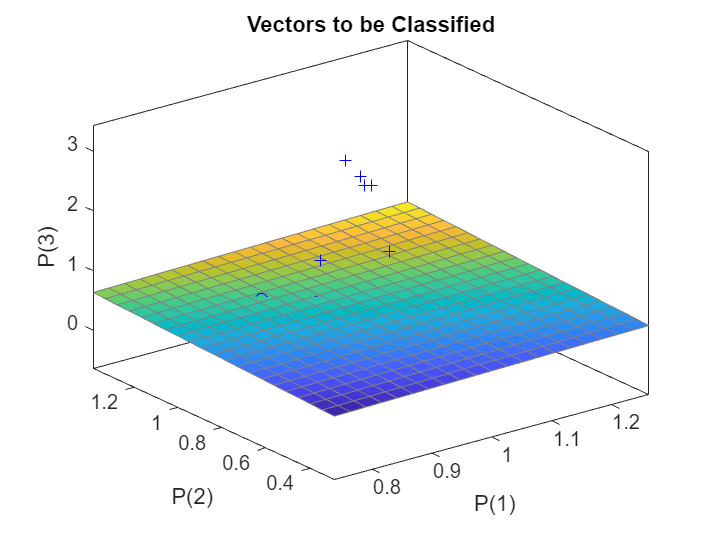

%国家类型的自适应分类(变量除以平均值)
clear                                       %清理内存
P=[1.0777 	1.0464 	1.0900 	1.0723 	0.9960 	1.0219 	1.0328 	0.9088 	0.9715 	0.9633 	0.9933 	0.9510 	0.9456 	0.9088 
1.0784 	1.0784 	1.0784 	1.0784 	1.0533 	0.8126 	1.0500 	1.0838 	1.0697 	0.9934 	1.0784 	1.0108 	0.8474 	0.5849 
2.0117 	2.5255 	1.9840 	2.1763 	1.0248 	1.5116 	0.3384 	0.5511 	0.4102 	0.5124 	0.2860 	0.3658 	0.3443 	0.2594]; 
                                            %输入变量
T=[1 1 1 1 1 1 0 0 0 0 0 0 0 0];            %目标输出
plotpv(P,T);                                %绘制训练样品分类立体图
net=newp(minmax(P),1);                      %创建一个感知器网络
handle=plotpc(net.iw{1},net.b{1});          %在训练前的分类图中绘制分界面
net.adaptParam.passes=2;                    %设定自适应循环次数
for a=1:10                                  %指定迭代次数为25次
    [net,Y,e]=adapt(net,P,T);               %调用自适应函数训练网络
    handle=plotpc(net.iw{1},net.b{1},handle);
    drawnow;                                %添加分类界面
end;

Y                                           %输出训练样品的分类结果

Y =      1     1     1     1     1     1     0     0     0     0     0     0     0     0


P_test=[1.0723 	1.0655 	0.9565 	0.9265 
1.0784 	1.0555 	1.0664 	0.9019 
1.7624 	1.1894 	0.4818 	0.2649];            %输入判样品信号
y=sim(net,P_test);y                         %待判样品的仿真分类结果

y =      1     1     0     0


w=net.iw{1,1}                               %输出权数向量

w =    -1.3708   -1.5389    8.1663


b=net.b{1}                                  %输出阈值

b = -2